## Homework 2.3

### a. Newton method to find x* root in the interval (0, pi/2)

Plot the function

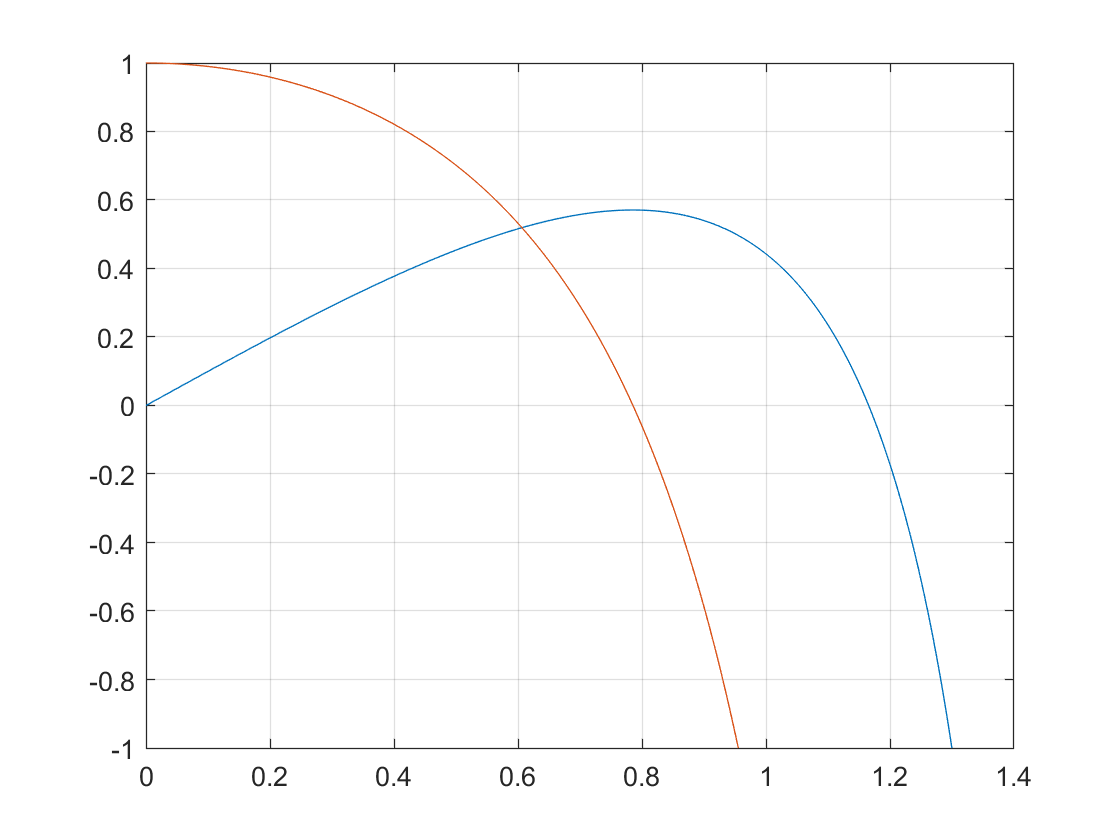

clear all;
close all;
clc;

f = @(x) 2*x - tan(x);
df = @(x) 2 - (1./(cos(x).^2));

x = linspace(0, pi/2, 1000);

figure();
plot(x, f(x));
hold on;
plot(x, df(x));
hold off;

grid on;
ylim([-1, 1]);

Call the Newton method

x0 = 1;
tol = 10e-15;
Nmax = 10e6;

[x, x_iter] = newton(f, df, x0, tol, Nmax);

x_ = x;

fprintf('x: %g', x);

x: 1.16556

display(x_iter);

x_iter =     1.0000    1.3105    1.2239    1.1761    1.1659    1.1656    1.1656    1.1656    1.1656


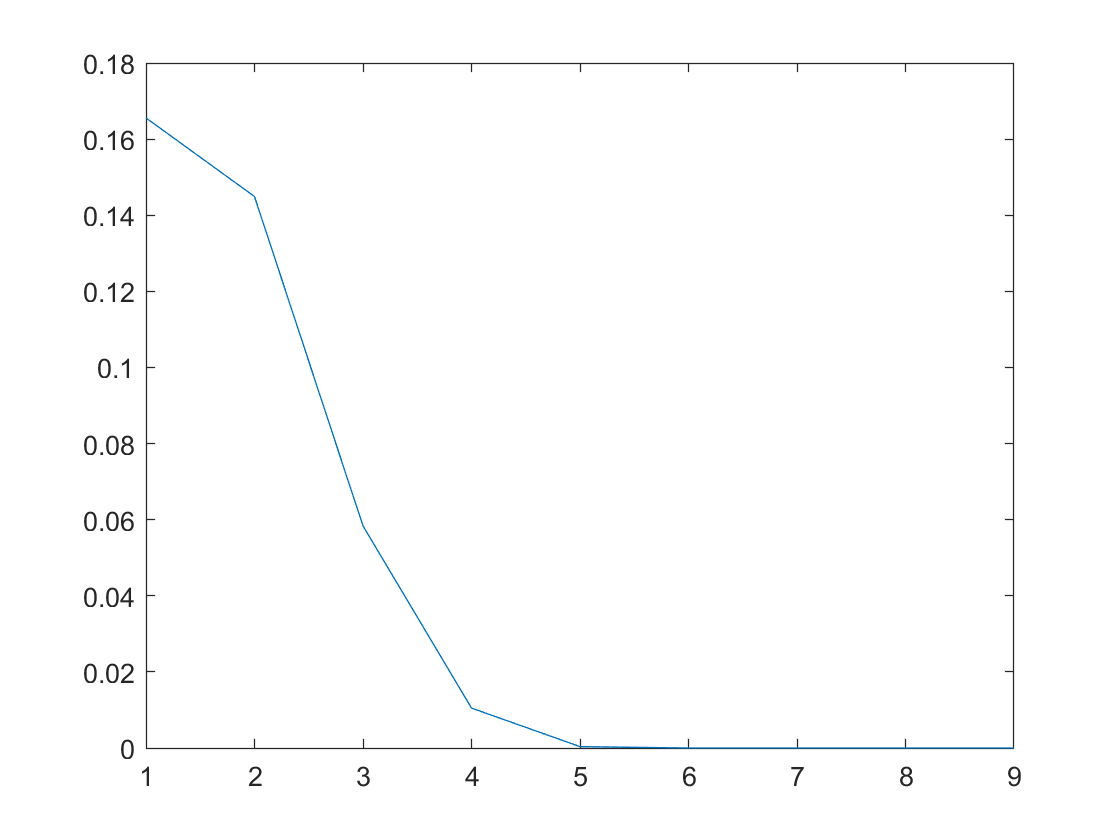


error = abs(x_iter-x);
figure();
plot(error);

### b. Newton method to find x* root in the interval (-pi/2, pi/2)

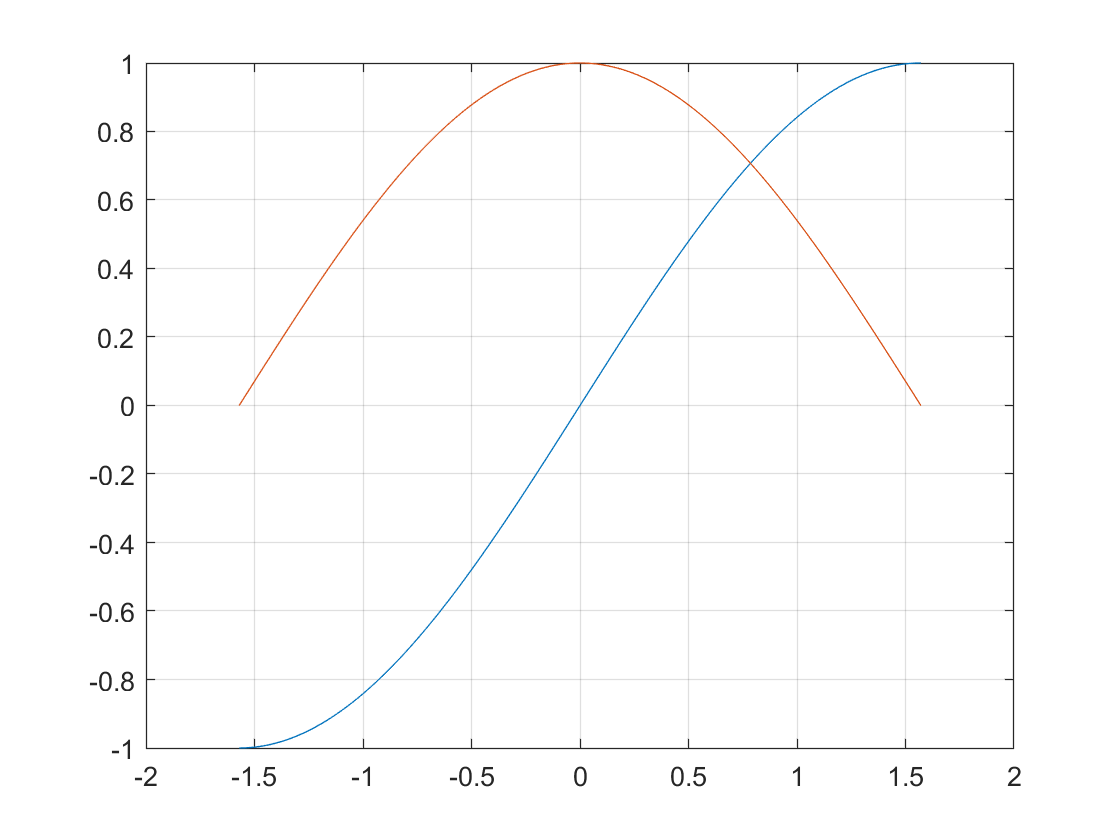

g = @(x) sin(x);
dg = @(x) cos(x);

x = linspace(-pi/2, pi/2, 1000);

figure();
plot(x, g(x));
hold on;
plot(x, dg(x));
hold off;

grid on;
ylim([-1, 1]);

Call the Newton method

x0 = x_;
tol = 10e-15;
Nmax = 10e6;

[x, x_iter] = newton(g, dg, x0, tol, Nmax);

fprintf('x: %g', x);

x: 21.9911

display(x_iter);

x_iter =     1.1656   -1.1656    1.1656   -1.1656    1.1656   -1.1656    1.1656   -1.1656    1.1656   -1.1656    1.1656   -1.1656    1.1656   -1.1656    1.1656   -1.1656    1.1656   -1.1659    1.1674   -1.1757    1.2222   -1.5294   22.6292   21.8877   21.9915   21.9911   21.9911   21.9911


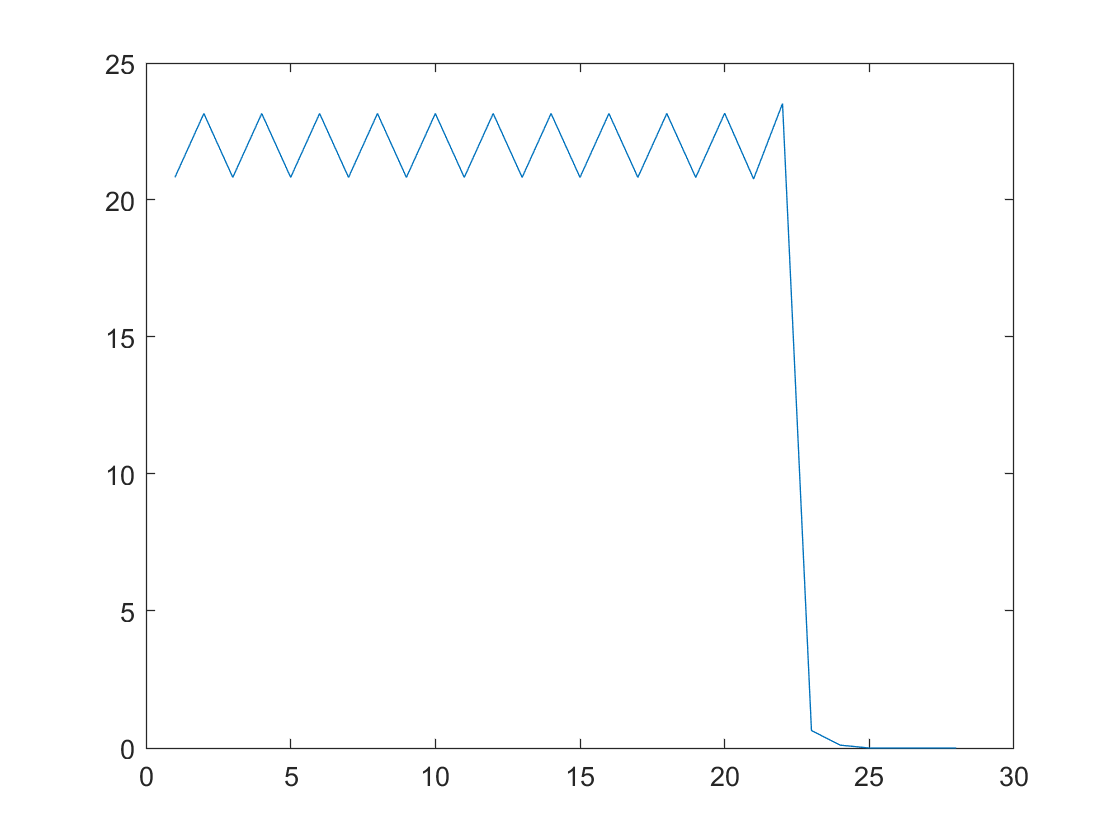


error = abs(x_iter-x);
figure();
plot(error);

There's a big oscillation

Functions

function [x, x_iter] = newton(f, df, x0, tol, Nmax)
    % Nmax since we don't know a priori if with the passed
    % tol we will reach a convergence

    x_iter(1) = x0;
    
    for k = 2:Nmax
        
        % Check if the derivative is zero or simil-zero
        if abs(df(x_iter(k-1))) < 1e-8
            break;
        end
        
        x_iter(k) = x_iter(k-1) - (f(x_iter(k-1)) / df(x_iter(k-1)));
    
        if abs(x_iter(k) - x_iter(k-1)) < tol
            break;
        end
    end
    
    x = x_iter(end);
end